% Set the parameters
duration = 5; % Recording duration in seconds
fs = 44100; % Common Sampling frequency

% Adjust the cutoff frequency based on the background sound frequency
cutoffFrequency = 10; % Set to a value higher than the background sound frequency

% Record voice
recObj = audiorecorder(fs, 16, 1);
disp('Press any key to start recording.');

Press any key to start recording.


pause;
disp('Start recording.');

Start recording.


recordblocking(recObj, duration);
disp('End of recording.');

End of recording.


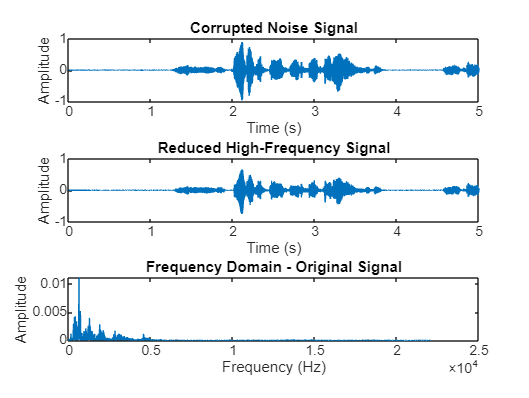


% Get the recorded data
corruptedNoise = getaudiodata(recObj);

% Display the original voice signal
figure;
subplot(3, 1, 1);
plot((0:length(corruptedNoise)-1)/fs, corruptedNoise);
title('Corrupted Noise Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Apply a low-pass filter using 'lowpass' function to reduce high-frequency signals
lowFrequencySignal = lowpass(corruptedNoise, cutoffFrequency, fs);

% Display the low-frequency signal after reducing high-frequency components
subplot(3, 1, 2);
plot((0:length(lowFrequencySignal)-1)/fs, lowFrequencySignal);
title('Reduced High-Frequency Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Play the original and filtered voice signals
sound(corruptedNoise, fs);
pause(duration + 1); % Pause to ensure the first sound is completed before the next
sound(lowFrequencySignal, fs);

% Save the low-frequency signal (optional)
audiowrite('reduced_high_frequency_signal.wav', lowFrequencySignal, fs);

% Apply FFT to the original signal
N_original = length(corruptedNoise);
f_original = (0:N_original/2) * (fs/N_original);
Axk_original = 2 * abs(fft(corruptedNoise) / N_original);
Axk_original(1) = Axk_original(1) / 2;

% Plot frequency domain of original signal
subplot(3, 1, 3);
plot(f_original, Axk_original(1:N_original/2+1));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Domain - Original Signal');

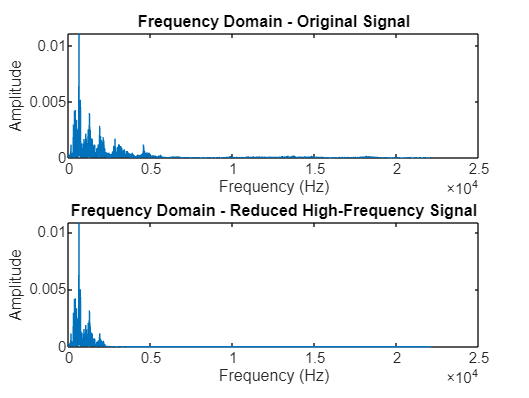


% Create a new figure for the frequency domain of the low-frequency signal
figure;
subplot(2, 1, 1);
plot(f_original, Axk_original(1:N_original/2+1));
title('Frequency Domain - Original Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

% Apply FFT to the low-frequency signal
N_lowFrequency = length(lowFrequencySignal);
f_lowFrequency = (0:N_lowFrequency/2) * (fs/N_lowFrequency);
Axk_lowFrequency = 2 * abs(fft(lowFrequencySignal) / N_lowFrequency);
Axk_lowFrequency(1) = Axk_lowFrequency(1) / 2;

% Plot frequency domain of low-frequency signal
subplot(2, 1, 2);
plot(f_lowFrequency, Axk_lowFrequency(1:N_lowFrequency/2+1));
title('Frequency Domain - Reduced High-Frequency Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');